# DSSS Receiver for Search and Rescue Tracking System

This example shows how to implement a Direct Sequence Spread Spectrum (DSSS) receiver that uses Offset Quadrature Phase Shift Keying (OQPSK) modulation. The example generates a DSSS burst that mimics the signal defined in the second-generation COSPAS-SARSAT (Search And Rescue Satellite-Aided Tracking) Emergency Locator Transmitter (ELT) rescue beacon specification [1], passes the burst through a channel, and simulates a receiver capable of detecting, synchronizing, despreading, and decoding the burst.

## COSPAS-SARSAT

The COSPAS-SARSAT system is a second-generation satellite system for ELTs that are used as distress beacons in a life-threatening emergency to summon assistance from government authorities [2]. The transmission modulation uses DSSS to spread data bits modulated with OQPSK. DSSS adds signal gain in the form of a spreading gain and is ideal for long-distance transmissions. OQPSK is a modulation that is resistant to amplitude variations, and its constant-envelope and continuous-phase signal properties are ideal for efficient amplification using power amplifiers. A one-second packet burst is created with the following information:

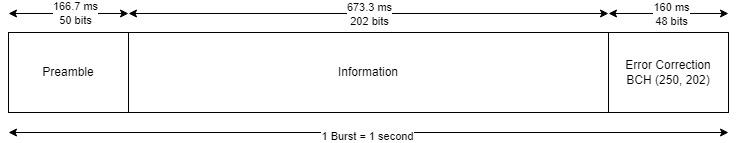

- **Preamble** [50 bits]: All preamble bits are zero.

- **Information Message** [202 bits]: Location data, identification codes, and receiver status.

- **Parity **[48 bits]: The 202 information message bits are encoded using an error correction code.

The burst consists of a preamble, followed by the information payload, and ending with parity bits used for error detection and correction of the information payload. The preamble assists the receiver in establishing synchronization quickly with high probability of detection and low probability of false alarm. To transmit the emergency signal as long as possible, battery life is preserved by transmitting the burst once every 30 seconds with a random back-off time to prevent another emergency beacon from accidentally transmitting at the same exact time as another beacon. This means that the transmission is treated as a random-access burst. Consequently, the signal start time, frequency offset, phase offset, timing offset, signal strength, and channel are all unknown at the receiver.

The total size of the packet is 300 bits. Each bit is spread using a spreading factor of 256, with the in-phase (I) and quadrature (Q) branches of the OQPSK modulation spread using unique orthogonal spreading codes. Since the modulation order of OQPSK is two bits per symbol, two bits are sent for every 256 OQPSK symbols. With a specified chip rate of 38400 chips per second, the packet duration is one second (150 bits transmitted per I and Q branch with each bit spread over 256 OQPSK symbols).

## Example Overview

This example models an ELT transmitter and ELT receiver. The transmitter generates one burst after a user-selectable number of seconds. The receiver can travel in an aircraft or satellite. This example can generate impairments such as: 

- Large-scale fading from path loss

- Additive White Gaussian Noise (AWGN) from thermal noise

- Frequency and phase offset from transmitter-receiver oscillator mismatch and Doppler effects

### Settings

Set the simulation and receiver parameters. Range affects received signal power due to path loss. Velocity introduces Doppler effects such as from receivers in a search aircraft traveling at 200 meters per second, or receivers in Low Earth Orbit (LEO) traveling at 7800 meters per second that can add up to approximately 10 kHz of frequency offset.

settings.distance       = 1; % distance between transmitter and receiver in meters
settings.velocity       = -7000; % relative velocity between transmitter and receiver in m/s
settings.oversampling   = 4; % oversampling factor for tx and rx (must be >= 2)
settings.txPower        = 33; % transmit power in dBm (33 dBm max)
settings.simTime        = 5; % length of simulation in seconds
settings.burstDelay     = 3.5; % number of seconds until burst is received
settings.maxDoppler     = 12000; % maximum detected Doppler in Hz

### **Impairments**

The COSPAS-SARSAT transmission frequency is 406.05 MHz, with a tolerance of +/- 1200 Hz or approximately 3 ppm. Specify the frequency offset between the transmitter and receiver due to oscillator mismatch.

impairments.rxFreqOffset = 1200; % receiver frequency offset Hz

Set the parameters for the transmission protocol. The parameters for the COSPAS-SARSAT system are detailed in [1].

system.fc              = 406.05;   % carrier frequency in MHz
system.preambleLength  = 50;       % preamble length in bits
system.payloadLength   = 202;      % payload length in bits
system.parityLength    = 48;       % parity length in bits
system.chipRate        = 38400;    % chips per second
system.spreadingFactor = 256;      % DSSS spreading factor

Compute parameters derived from the settings.

sps = 2 * settings.oversampling; % define samples per symbol
fs = system.chipRate * sps;    % define the sampling frequency

spreadingFactor_IQ = system.spreadingFactor / 2;

packetLength = system.preambleLength + ...
               system.payloadLength + ...
               system.parityLength;    % packet length in bits
numChips = spreadingFactor_IQ * packetLength; % number of chips in the packet
numPreambleChips = system.preambleLength * spreadingFactor_IQ;
numBurstSamples = (packetLength/2) * system.spreadingFactor * sps;

dopplerShift = (system.fc*1e6) * settings.velocity / physconst('LightSpeed');

checkSettings(settings); % check restrictions on settings

rng(1973); % set a random seed for repeatability

## DSSS Transmitter

Direct sequence spread spectrum communications is a method for encoding a stream of bits with a long sequence of bits that have the property of zero autocorrelation. This sequence of bits is known as a pseudo-random noise (PRN) sequence. This method "spreads" the incoming bits such that the spectrum bandwidth increases, and the power spectrum of the signal resembles bandlimited white noise due to the zero-autocorrelation property. This characteristic makes DSSS resistant to narrowband interference and jamming. The spreading also adds information to the signal that is seen as a spreading gain which is dependent on the spreading factor, or the number of spreading bits per input bit.

As a generic example of DSSS spreading, consider the first 24 bits of the PRN sequence below. Choose a spreading factor of 4, such that every encoded bit is spread with four spreading bits. Encode six bits of information such that a logical 1 inverts the PRN sequence for four bits and uses those as the spreading bits, while a logical 0 preserves the PRN sequence for the four bits (the "Mapped sequence" below, where underlined bits denote the inverse operation).

- `PRN sequence:      1000 0010 0001 1000 1010 0111`

- `Information bits:  1    0    0    1    1    0`

- `Mapped sequence:   ``1000`` 0010 0001 ``1000` `1010`` 0111`

- `DSSS output bits:  0111 0010 0001 0111 0101 0111`

The DSSS transmitter takes an incoming serial bitstream and splits it into two streams: the in-phase (I) stream takes the odd bits, and the quadrature (Q) stream takes the even bits. Two PRN sequence generators output 38400 bits for each stream to use as the spreading sequence. The spreading codes are based on an $x^{23}+x^{18}+1$ generator polynomial. The I and Q streams use a unique sequence by initializing the PRN generator with predefined polynomials. The Q stream is offset by one half of a chip to produce the offset QPSK constellation.

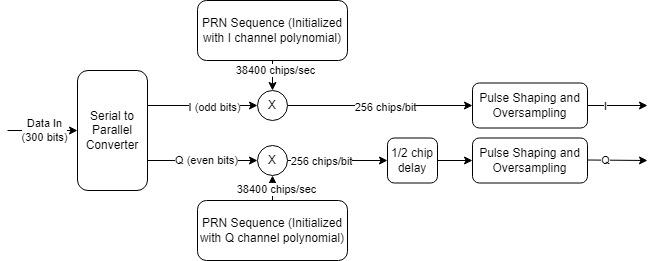

Generate the PRN sequences using `comm.PNSequence`. The transmitter and receiver use this sequence to spread and despread the data, respectively.

% Configure and initialize the PRN generators for the I and Q streams
DSSS.normalI = [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 1]; % COSPAS-SARSAT Normal I mode
DSSS.normalQ = [0 0 1 1 0 1 0 1 1 0 0 0 0 0 1 1 1 1 1 1 1 0 0]; % COSPAS-SARSAT Normal Q mode
DSSS.hLFSRI = comm.PNSequence( ...
    Polynomial =        'X23+X18+1',  ...
    InitialConditions = DSSS.normalI, ...
    SamplesPerFrame =   numChips);

DSSS.hLFSRQ = comm.PNSequence( ...
    Polynomial =        'X23+X18+1',  ...
    InitialConditions = DSSS.normalQ, ...
    SamplesPerFrame =   numChips);

% Generate the PRN sequences
DSSS.PRN_I = DSSS.hLFSRI();
DSSS.PRN_Q = DSSS.hLFSRQ();

The COSPAS-SARSAT specification lists the first 64 chips of the normal I and Q sequences to verify correct implementation. Use the `dec2hex` function to output the hexadecimal values for verification against the standard.

dec2hex(bit2int(DSSS.PRN_I(1:64), 16))

ans = 4×4 char array
    '8000'
    '0108'
    '4212'
    '84A1'


dec2hex(bit2int(DSSS.PRN_Q(1:64), 16))

ans = 4×4 char array
    '3F83'
    '58BA'
    'D030'
    'F231'


Create samples of the preamble for use in a preamble detector to detect the preamble. Because the COSPAS-SARSAT specification does not specify the type of pulse shaping to be used, create the samples using QPSK at the symbol rate.

preambleQPSK = pskmod(reshape([DSSS.PRN_I(1:numPreambleChips/2) DSSS.PRN_Q(1:numPreambleChips/2)].', ...
    1,numPreambleChips).',4,pi/4,InputType='bit');

Generate a transmit burst using the COSPAS-SARSAT specification and user-defined settings.

tx = helperDSSSTransmitter(system,sps,DSSS);

OQPSK modulation produces a signal with constant envelope. This type of signal minimizes out-of-band emissions from discontinuous phase and maximizes transmit power output from power amplifiers because it avoids the nonlinear amplifier region. Show that the transmitted burst is a constant envelope signal.

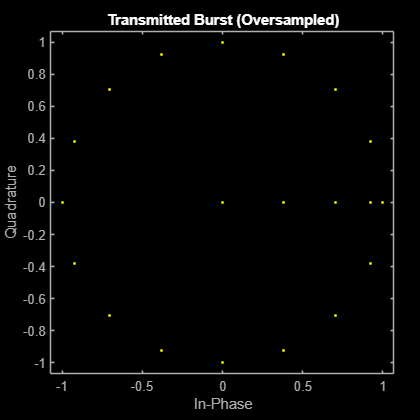

% Show the oversampled transmitted constellation
figure;
scatterplot(tx.Samples);
title('Transmitted Burst (Oversampled)');

## Channel and Receiver Impairments

Create an over-the-air (OTA) buffer that contains all samples for the entire simulation. Add an offset to the transmission burst to insert a period of silence before the burst is transmitted. Apply frequency offset due to Doppler from the receiver speed. 

txOffset = floor(settings.burstDelay * fs); % number of empty samples before the transmission burst appears in the buffer
otaBuffer = complex(zeros(floor(settings.simTime*fs),1));
otaBuffer(txOffset:txOffset+numBurstSamples-1) = tx.Samples;

% Apply frequency offset due to Doppler from the receiver speed
otaBuffer = frequencyOffset(otaBuffer,fs,dopplerShift);

### Path Loss Modeling

Thermal noise density at 25 degrees Celsius is -174 dBm/Hz. The bandwidth of COSPAS is 2*chipRate, or 76.8 kHz. The thermal noise for a 76.8 kHz receiver is -174 + 10*log10(76.8e3) = -125.1 dBm.

Using the default parameters, the receiver is at a distance of 300km. The free space path loss is `fspl`(300e3, 3e8 / 406.05e6) = 134.2 dB. Minimum equivalent isotropic radiated power (EIRP) is 33 dBm. Therefore, the received power level is 33 - 134.2 = -101.2 dBm. This gives a 24 dB SNR. With a spreading factor of 256, the spreading gain adds 24.1 dB when considering Eb/No.

Calculate the SNR resulting from the given transmit power and signal power loss due to distance between the transmitter and receiver.

noiseFloorPow = -174 + pow2db(2*system.chipRate);  % noise floor (dBm)
pathLoss = fspl(settings.distance,physconst('LightSpeed')/(system.fc*1e6));
SNR = (settings.txPower - pathLoss) - noiseFloorPow;
fprintf('Simulation SNR = %4.1f dB\n',SNR);

Simulation SNR = 133.5 dB


### Apply Receiver Impairments

Frequency offset originates from the mismatch of the transmitter and receiver's oscillators. AWGN originates from the receiver's front end. Apply both impairments to the received over-the-air (OTA) samples.

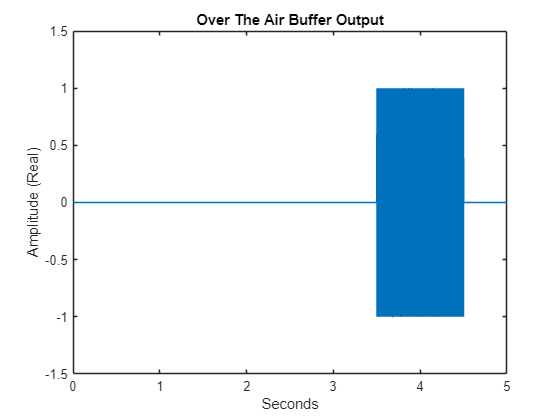

% Add frequency offset from receiver offset
otaBuffer = frequencyOffset(otaBuffer,fs,impairments.rxFreqOffset);

% Add AWGN according to the path loss calculation
otaBuffer = awgn(otaBuffer,SNR,'measured');

% Plot the OTA buffer
figure;
plot(settings.simTime/length(otaBuffer):settings.simTime/length(otaBuffer):settings.simTime,real(otaBuffer));
title('Over The Air Buffer Output');
xlabel('Seconds');
ylabel('Amplitude (Real)');

## Receiver

The receiver structure is shown below. Preamble detection is needed to detect and capture a complete burst in the sample buffer for processing. The receiver faces challenges of unknown transmission time, frequency offset from dissimilar radio oscillators and Doppler shift, phase offset from asynchronous sampling, timing drift from dissimilar clocks, and channel conditions from path loss and multipath. All these impairments must be compensated for by the end of the preamble so that the payload data is synchronized for demodulation.

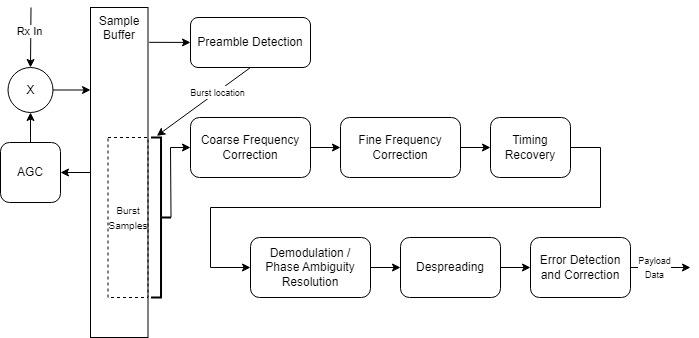

The automatic gain control (AGC) adjusts the incoming signal amplitudes that are affected by path loss. Preamble detection continuously searches for the beginning of a COSPAS-SARSAT burst within the sample buffer. Once a burst is detected, the burst samples are extracted from the sample buffer and passed on to the coarse frequency correction block to estimate the frequency offset and correct the offset. Fine frequency correction is done next to get the frequency offset as close to zero as possible. Timing recovery takes the oversampled signal and resolves the proper phase such that the constellation aligns with the reference QPSK constellation. The constant phase alignment also compensates for timing drift. The signal is then demodulated several times with different phase and symbol offsets to resolve phase ambiguity resulting from the frequency correction and timing recovery algorithms. The QPSK symbols are despread and the decoded bits are passed through an error detection block to detect and correct errors within the payload data.

### Sample Buffering

Since beacon transmissions are asynchronous, part of the burst may be captured in one buffer, while the latter part of the burst may be contained in the next buffer. To ensure capture of a burst within a single buffer, a double-buffering scheme is used where a sample buffer is created with a length that can store two complete transmission bursts. The sample buffer is partitioned into two sections: a previous sample buffer and a recent sample buffer. The second half of the sample buffer is filled with one second of the most recent samples, while the first half of the sample buffer contains the previous samples. When the most recent sample buffer is filled, a search for the preamble may be done across both sample buffers. If no preamble is detected, the recent sample buffer replaces the older sample buffer. The length of the sample buffer guarantees that a complete burst spans both sample buffers. In the figure below, the entire burst is contained within the sample buffer at time t2.

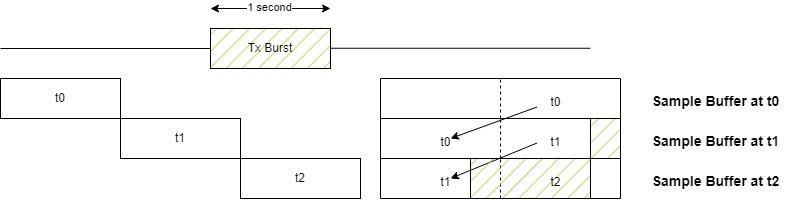

Create a sample buffer with a length twice that needed to store a complete transmission burst. Begin feeding in one second of samples, apply automatic gain control, and search for the preamble.

numBuffers = floor(length(otaBuffer)/numBurstSamples);
sampleBuffer = complex(randn(numBurstSamples*2,1),randn(numBurstSamples*2,1)); % start with empty buffer of AWGN

% Load in one second of samples then search for the preamble in the sample
% buffer
for n=1:numBuffers

    % Shift the last burst samples to front of buffer
    sampleBuffer(1:numBurstSamples) = sampleBuffer(numBurstSamples+1:end);

    % Read in next burst
    nextBurstIdx = (n-1)*numBurstSamples + 1;
    sampleBuffer(numBurstSamples+1:end) = otaBuffer(nextBurstIdx:nextBurstIdx+numBurstSamples-1); % Rx in

### Automatic Gain Control (AGC)

The receiver's dynamic range must be able to detect faint signals from maximum distance up to strong signals received at close range. The bursty nature of ELT signals means that the AGC reaches maximum gain in between transmission bursts, then must quickly adjust the gain when the burst is received at the receiver front end to avoid signal saturation at the power amplifier and/or analog-to-digital converter (ADC).

Normalize the receiver input signals using the `comm.AGC` system object such that the signal power is unity. Configure the AGC to average over 10 symbols and set the maximum gain to be able to amplify down to the noise floor. This example does not model quantization noise effects from the ADC.

    % Configure the AGC and process the samples

Preamble not found after 1 seconds
Preamble not found after 2 seconds
Preamble not found after 3 seconds
Preamble not found after 4 seconds


Found preamble at correlation buffer number 6, index 19201, sample index 153602


    agc = comm.AGC( ...
        AdaptationStepSize = 0.01, ...
        AveragingLength =    10*sps, ...
        MaxPowerGain =       210);
    [rxAGCSamples,pwrLevel] = agc(sampleBuffer);
    
    % Saturate signals to prevent false preamble detection during correlation
    rxAGCSamples = saturate(rxAGCSamples,1.2);

### Preamble Detection

The first cluster of samples of the preamble are assumed to be unusable while the AGC adjusts the input received signal power to the proper setpoint. Use only the latter part of the preamble for preamble detection by specifying an offset. Correlation with a long preamble results in lower probability of false alarm (false detection of preambles) in low SNR, but it is susceptible to low probability of detection when frequency offset is high. Shorten the length of the correlated preamble to combat frequency offset effects but maintain low false alarm probability. Frequency offset adversely affects correlator-based preamble detection, so different frequency offsets are applied to the reference preamble during the preamble search.

Correlate the preamble sequence against the sample buffer across different frequency offsets to detect the frequency-shifted preamble. 

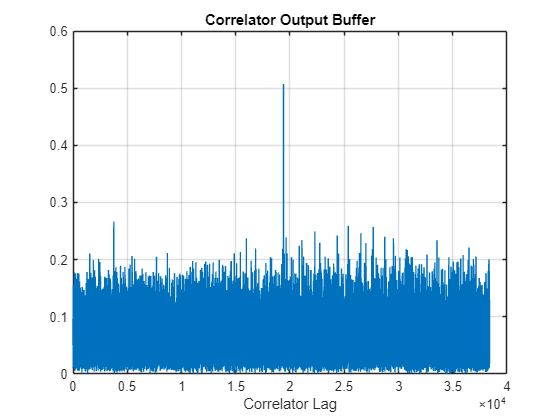

    % Increase to detect the preamble symbols after AGC convergence during the first
    % few preamble symbols

    preambleDetectionOffset = 200; % in symbols
    % Shorten the length of the preamble to correlate against to avoid frequency offset from
    % decorrelating the reference preamble with the received preamble
    preambleDetectionLength = 175; % in symbols
    tx.preambleChips = preambleQPSK(1+preambleDetectionOffset:preambleDetectionLength+preambleDetectionOffset);
    
    % Convert from OQPSK to QPSK for symbol-based preamble detection
    sampleBufferQPSK = [real(rxAGCSamples(1:end-sps/2)) + 1i*imag(rxAGCSamples(sps/2+1:end)); zeros(sps/2,1)];
    
    % Detect the preamble across different frequency offsets
    for preambleFreqOffset = -settings.maxDoppler:150:settings.maxDoppler
        % Add frequency offset to the preamble
        preambleShifted = frequencyOffset(tx.preambleChips,system.chipRate,preambleFreqOffset);

Estimated coarse frequency offset = -8.281 kHz


Estimation error =  0.004 Hz


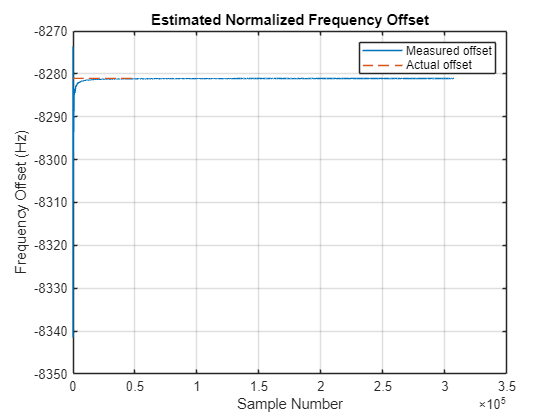

        % Get the start index of the preamble. Look for a preamble only in the
        % first half of the double-buffered sample buffer.
        [startSampIdx,corrBuffer] = helperPolyphaseCorrelator( ...
            sampleBufferQPSK(1:numBurstSamples),preambleShifted,sps,preambleDetectionOffset);
        if ~isempty(startSampIdx)
            break; % break out of frequency search loop
        end
    end
    if isempty(startSampIdx)
        disp(['Preamble not found after ', num2str(n), ' seconds']);
    else
        break; % break out of preamble search loop
    end

end
if isempty(startSampIdx)
    error('Preamble not detected amongst simulation samples.');
end


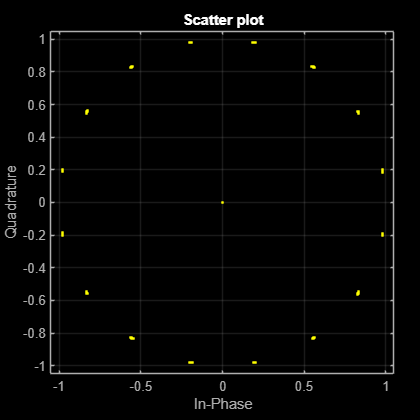

% Plot the correlator output
figure;
plot(abs(corrBuffer));
grid on;

title('Correlator Output Buffer');
xlabel('Correlator Lag');
% Extract the transmission burst from the sample buffer. Collect 20 more
% chips at the end for possible timing adjustments
rxBurst = sampleBuffer(startSampIdx:startSampIdx+((numChips+20)*sps)-1);

### Frequency and Phase Offset Compensation

Frequency and timing offset will cause the constellation of the detected signal to rotate and display non-constant envelope characteristics. The downstream receiver processing will detect the offsets and correct them to produce a stable signal suitable for demodulation and decoding. Use the `comm.CoarseFrequencyCompensator `system object to estimate the carrier frequency offset over the received burst and apply the frequency offset to the sample buffer.

% Estimate and correct carrier offset
coarse = comm.CoarseFrequencyCompensator( ...
    Modulation =           "OQPSK", ...
    SamplesPerSymbol =     sps, ...

Found preamble at correlation buffer number 3, index 1, sample index 1


    SampleRate =           fs, ...
    FrequencyResolution =  1);
[coarseSyncOut,coarseEst] = coarse(rxBurst);
fprintf('Estimated coarse frequency offset = %6.3f kHz\n',coarseEst/1000);
fprintf('Estimation error = %6.3f Hz\n',coarseEst-(dopplerShift+impairments.rxFreqOffset));

Use the` comm.CarrierSynchronize`r system object to detect and correct smaller carrier frequency and phase offsets. This object aligns the received constellation to the QPSK reference points to compensate for phase offset.

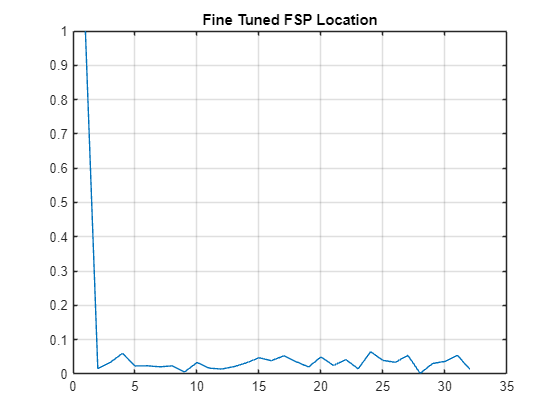

carrierSync = comm.CarrierSynchronizer( ...
    Modulation =                "OQPSK", ...
    NormalizedLoopBandwidth=    0.01, ...
    DampingFactor =             0.707, ...

    SamplesPerSymbol =          sps);
[carrierSyncOut,phErr] = carrierSync(coarseSyncOut);

Show that the frequency offset estimation converges to the actual frequency offset at the end of the preamble and prior to the start of the payload data.

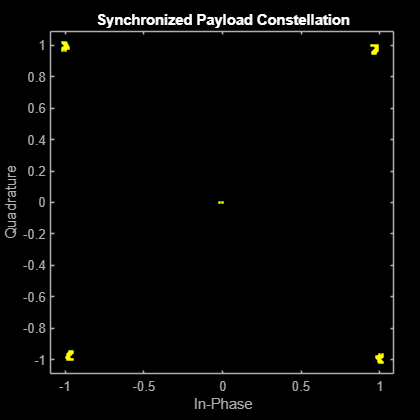

estFreqOffset = diff(phErr) * fs / (2*pi);
rmean = cumsum(estFreqOffset)./(1:length(estFreqOffset))';
figure;
plot(coarseEst+rmean);
title('Estimated Normalized Frequency Offset');
xlabel('Sample Number');
ylabel('Frequency Offset (Hz)');
hold on;
plot((dopplerShift+impairments.rxFreqOffset)*ones(fs*(system.preambleLength/packetLength),1),'--');
legend({'Measured offset','Actual offset'});
grid;

Plot the frequency-corrected constellation of the payload data. The constellation should now have a near-constant envelope shape.

figure;
scatterplot(carrierSyncOut(numPreambleChips+1:end))
grid on

### Path Detection

The location of the preamble start might have shifted slightly after frequency offset correction. Repeat preamble detection using the entire preamble for maximum resolution.

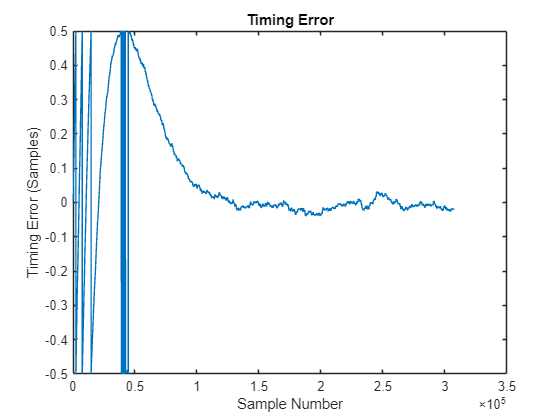

% Convert from OQPSK to QPSK
carrierSyncOutQPSK = [real(carrierSyncOut(1:end-sps/2)) + 1i*imag(carrierSyncOut(sps/2+1:end)); zeros(sps/2,1)];


preambleOffsetChips = 5000; % preamble correlation offset in chips
preambleOffset = preambleOffsetChips / 2; 
preamble0 = preambleQPSK(preambleOffset+1:end);
[FSPSampIdx,corrBuffer2] = helperPolyphaseCorrelator(carrierSyncOutQPSK,preamble0,sps,preambleOffset);
if isempty(FSPSampIdx)
    error('Preamble lost. Check frequency tracking.');
end

% Plot the correlator output
figure;
plot(abs(corrBuffer2(1+preambleOffset:32+preambleOffset)));
grid on;
title('Fine Tuned FSP Location');

### Timing Recovery, Demodulation, and Phase Resolution

After frequency and phase offset compensation, perform timing recovery on the signal. During OQPSK timing recovery, the` comm.SymbolSynchronizer` system object delays the quadrature component, performs synchronization, and converts the oversampled OQPSK signal to symbol-rate QPSK such that the output is a conventional QPSK constellation.

% Timing recovery of OQPSK signal, via its QPSK-equivalent version

Preamble detected


symbolSynchronizer = comm.SymbolSynchronizer( ...
    Modulation =       'OQPSK', ...
    NormalizedLoopBandwidth = 0.001, ...
    DetectorGain =     4, ...
    DampingFactor =    2, ...
    SamplesPerSymbol = sps);
[syncedQPSK,timingError] = symbolSynchronizer(carrierSyncOut(FSPSampIdx:end));

figure;
scatterplot(syncedQPSK(numPreambleChips+1:end)); % plot the payload constellation
title('Synchronized Payload Constellation');

Plot the timing error. Differences in transmitter and receiver clocks show as a positive or negative sloping error over time.

figure;
plot((timingError-0.5)-sign(timingError-0.5)*0.5);
title('Timing Error');
xlabel('Sample Number');
ylabel('Timing Error (Samples)');

### Demodulation and Phase Ambiguity Resolution

Use the `pskdemod` function to demodulate the OQPSK samples. OQPSK modulation and demodulation incur system delays that depend on the pulse shaping used. Account for the system delay when extracting the I and Q bitstreams for the demodulator.

During frequency compensation and timing recovery, the received constellation may rotate significantly while the algorithms lock on to the proper frequency and phase. Both algorithms are designed to rotate and stabilize the received constellation to match the reference QPSK constellation, but due to the symmetry of the QPSK constellation the received signal may be out of phase by 90, 180, or -90 degrees. Furthermore, the signal timing may have drifted such that the I and Q streams are reversed due to the time offset of the I and Q streams. Test all 90 degree phase rotations and I-Q/Q-I combinations to determine the proper phase and timing using the preamble as a reference source.

preambleDetector = comm.PreambleDetector(Threshold=1400,Detections='First');

% Form the chip sequence of the preamble for phase ambiguity resolution
preambleChips = reshape([DSSS.PRN_I(1:3200).'; DSSS.PRN_Q(1:3200).'],[],1);

% Rotate the constellation 90 degrees and search for preamble
for p=0:1
    for k=0:3
        % Demodulate and extract out the I & Q bit streams
        rxSig = pskdemod(syncedQPSK*exp(1i*k*pi/2),4,pi/4,"OutputType","bit");
        rx.Ci = [rxSig(1:2:numChips*2);0];
        rx.Cq = [rxSig(2:2:numChips*2);0];
        
        % Use the preamble detector to search for the preamble sequence
        preambleSymbol = preambleChips-0.5;
        preambleTest = reshape([rx.Ci(1+p:3300+p) rx.Cq(1:3300)]',[],1)-0.5;
        preambleDetector.Preamble = preambleSymbol;
        [pIdx,pMet] = preambleDetector(preambleTest);
        release(preambleDetector);

Error correction detected 0 bit errors


    
        if ~isempty(pIdx)
            fprintf('Preamble detected\n');
            break;
        end
    end
    if ~isempty(pIdx)
        break;
    end
end
if isempty(pIdx)
    error('Preamble not decoded correctly');
end
% Compute the start indices for the I and Q streams
preambleTestStartIdx = pIdx - numPreambleChips + 1;
sIdxI = preambleTestStartIdx + 2*p;
sIdxQ = preambleTestStartIdx + 1;

% Extract preamble and payload
rx.Ci = rxSig(sIdxI:2:sIdxI+2*numChips-1);
rx.Cq = rxSig(sIdxQ:2:sIdxQ+2*numChips-1);

### DSSS Despreading

Detect the binary sequence by correlating the PRN sequence with the received chips. Reshape each I and Q chip vector into an array with 256 rows and 150 columns, with each column corresponding to one bit with spreading factor 256. If the chips in a column correlate with the PRN sequence, it is decoded as a logical 0. For maximum likelihood (ML) decoding, a logical 0 is detected when more than half of the chips (more than 128 chips) are correlated with the PRN sequence. Otherwise, it is a logical 1. Interleave the despread I and Q streams into a single bit stream.

% Correlate the PRN sequence with the received chips
Ibdn = (xor(rx.Ci, DSSS.PRN_I));
Qbdn = (xor(rx.Cq, DSSS.PRN_Q));
Ichips = reshape(Ibdn,system.spreadingFactor,[]);
Qchips = reshape(Qbdn,system.spreadingFactor,[]);

% Perform ML decoding
threshold = system.spreadingFactor/2;
Ibits = sum(Ichips,1) > threshold;
Qbits = sum(Qchips,1) > threshold;

% Demultiplex the I and Q streams into a single bitstream
despreadMessage = reshape([Ibits;Qbits],[],1);

### Error Detection and Correction

Perform Bose–Chaudhuri–Hocquenghem **(**BCH) decoding on the payload, detect the number of bit errors, and correct the bit errors. The (255,207) BCH code can correct up to six bit errors. If there are more than six bit errors detected, the codeword cannot be corrected.

hDecode = comm.BCHDecoder(255, 207, ...
    ['x48+x47+x46+x42+x41+x40+x39+x38+x37+x35+x33+x32+x31+x26+' ...
    'x24+x23+x22+x20+x19+x18+x17+x16+x13+x12+x11+x10+x7+x4+x2+x+1'], 202);
[rxPayload,errs] =  hDecode(despreadMessage(system.preambleLength+1:packetLength));

% The BCH decoder returns a negative number in errs if too many bit errors are detected to be correctable
if errs >= 0
    fprintf('Error correction detected %d bit errors\n',errs);
else
    fprintf('Error correction detected too many bit errors to correct\n');
end

## Summary

This example shows how to demodulate and decode DSSS signals from a generated DSSS signal modulated with OQPSK and distorted with realistic channel and receiver impairments. After preamble detection, System objects establish rapid synchronization by estimating the frequency and phase offset and performing timing recovery before decoding the payload data. Finally, the example shows how to demodulate, despread, and correct errors in the payload data.

MATLAB system objects and functions accelerated the system design and implementation by:

- Calculating error correction bits

- Generating the scrambling sequence

- Modulating with OQPSK

- Impairing the channel with frequency and phase offset

- Implementing automatic gain control

- Detecting the preamble

- Estimating coarse and fine frequency offset

- Recovering symbol timing

- Performing error detection and correction

## Helper Functions

This example uses these helper functions:

- [helperPolyphaseCorrelator.m](matlab:openExample('comm/DSSSReceiverForSARbasedTrackingSystemExample','supportingFile','helperPolyphaseCorrelator.m')) - Correlates a reference signal over different sample phases of a signal.

- [helperDSSSTransmitter.m](matlab:openExample('comm/DSSSReceiverForSARbasedTrackingSystemExample','supportingFile','helperDSSSTransmitter.m')) - Generate a DSSS baseband signal using OOQPSK modulation.

## Local Functions

function checkSettings(settings)
    % Check that user settings are valid
    validateattributes(settings.oversampling, ...
        {'numeric'},{'>=',2,'scalar','integer'},mfilename,'oversampling factor');
    if settings.simTime < settings.burstDelay + 1.0
        error('Set simulation time to be more than the burst delay plus one second.');
    end
    validateattributes(settings.txPower, ...
        {'numeric'},{'<=',33,'scalar'},mfilename,'transmit power');
end

function out = saturate(in,absLimit)
    % Saturate a complex-valued signal
    out = in .* min(absLimit,abs(in)) ./ abs(in);
end

## References

[1] COSPAS-SARSAT C/S T.018. "Specification for second-generation COSPAS-SARSAT 406-MHz distress beacons." *International Cospas-Sarsat Programme*

[2] [International COSPAS-SARSAT Program](https://www.cospas-sarsat.int/en/)

*Copyright 2023-2024 The MathWorks, Inc.*